% This file is to aid the derivation of the case of no damping,
% single ESS
syms wlim H D C1 C2 C3 Pe Pess t

wlim = 1/60;

H = 26.3378;
D = 1;
% Pe = 0.2;
tau = 1;

C1 = 0.0168; C2 = 0.0057; C3 = 0.0016;

w_exact(t) = 1/(2*H)*(C1/2*t^2 + (Pess-Pe-C2)*t + C3-tau*Pess + tau*Pess*exp(-t/tau))

$$w\_exact(t) = 1.5947e-04\,t^{2}-0.0190\,t\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)-0.0190\,\mathrm{Pess}+0.0190\,\mathrm{Pess}\,{\mathrm{e}}^{-t}+3.0375e-05$$

tn_exact = solve(diff(w_exact,t)==0, t); % exact solution with lambertw
wtn_exact(Pe,Pess) = subs(w_exact,t,tn_exact)

$$wtn\_exact(Pe, Pess) = \begin{array}{l} 1.5947e-04\,{\sigma_{1}}^{2}-0.0190\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)\,\sigma_{1}-0.0190\,\mathrm{Pess}+0.0190\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-W_{0}\left(59.5238\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}\right)-0.3393}+3.0375e-05\\ \mathrm{where}\\ \sigma_{1}=59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+W_{0}\left(59.5238\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}\right)+0.3393 \end{array}$$


w_approx1(t) = 1/(2*H)*(C1/2*t^2 + (Pess-Pe-C2)*t + C3-tau*Pess)

$$w\_approx1(t) = 1.5947e-04\,t^{2}-0.0190\,t\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)-0.0190\,\mathrm{Pess}+3.0375e-05$$

tn_approx1 = solve(diff(w_approx1,t)==0, t); % Ignoring the exp term for tn
wtn_approx1 = subs(w_exact,t,tn_approx1) % subbing into the expression with the exp term

$$wtn\_approx1(t) = 0.0190\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}-0.0190\,\mathrm{Pess}-0.0190\,\left(59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+0.3393\right)\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)+1.5947e-04\,{\left(59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+0.3393\right)}^{2}+3.0375e-05$$


wtn_approx2 = subs(w_approx1,t,tn_approx1) % Ignoring the exp term completely

$$wtn\_approx2(t) = 1.5947e-04\,{\left(59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+0.3393\right)}^{2}-0.0190\,\left(59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+0.3393\right)\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)-0.0190\,\mathrm{Pess}+3.0375e-05$$


Pe_base = sqrt(4*C1*H*wlim+2*C1*C3) - C2; % Pe limit without Pess. Linearize around (Pe_base, 0)

grad_Pe(Pe,Pess) = diff(wtn_exact,Pe)

$$grad\_Pe(Pe, Pess) = \begin{array}{l} 1.1300\,\mathrm{Pess}-1.1300\,\mathrm{Pe}+0.0190\,\sigma_{1}\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)-3.1893e-04\,\sigma_{1}\,\left(59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+\sigma_{2}+0.3393\right)-0.0190\,\sigma_{2}+0.0190\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-\sigma_{2}-0.3393}\,\sigma_{1}-0.0064\\ \mathrm{where}\\ \sigma_{1}=\frac{59.5238\,\sigma_{2}}{\sigma_{2}+1}-59.5238\\ \sigma_{2}=W_{0}\left(59.5238\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}\right) \end{array}$$

grad_Pess(Pe,Pess) = diff(wtn_exact,Pess)

$$grad\_Pess(Pe, Pess) = \begin{array}{l} 1.1300\,\mathrm{Pe}-1.1300\,\mathrm{Pess}+0.0190\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-\sigma_{2}-0.3393}-0.0190\,\sigma_{1}\,\left(\mathrm{Pe}-\mathrm{Pess}+0.0057\right)+3.1893e-04\,\sigma_{1}\,\left(59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+\sigma_{2}+0.3393\right)+0.0190\,\sigma_{2}-0.0190\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-\sigma_{2}-0.3393}\,\sigma_{1}-0.0125\\ \mathrm{where}\\ \sigma_{1}=\frac{0.0168\,{\mathrm{e}}^{59.5238\,\mathrm{Pe}-59.5238\,\mathrm{Pess}+0.3393}\,\left(59.5238\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}+3.5431e+03\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}\right)\,\sigma_{2}}{\mathrm{Pess}\,\left(\sigma_{2}+1\right)}-59.5238\\ \sigma_{2}=W_{0}\left(59.5238\,\mathrm{Pess}\,{\mathrm{e}}^{59.5238\,\mathrm{Pess}-59.5238\,\mathrm{Pe}-0.3393}\right) \end{array}$$

wtn_approx3 = -wlim + grad_Pe(Pe_base,0) * (Pe-Pe_base) + grad_Pess(Pe_base, 10e-6) * Pess

$$wtn\_approx3 = 0.1753\,\mathrm{Pess}-0.1943\,\mathrm{Pe}+0.0156$$


% Numerically solving the implicit equations for Pe given Pess
Pe_exact = [];
Pe_approx1 = [];
Pe_approx2 = [];
Pe_approx3 = [];
Pe_approx4 = [];
Pe_approx5 = [];
Pess_vec = -0.2:0.05:0.6;
for Pess_it = Pess_vec
    % exact solution of Pe for given Pess
    wtn_it1 = subs(wtn_exact,Pess, Pess_it);
    Pe_exact = cat(1,Pe_exact, double(max(solve(wtn_it1 == -wlim, Pe))));
    
    % solution with tn ignoring exp()
    wtn_it2 = subs(wtn_approx1,Pess, Pess_it);
    Pe_approx1 = cat(1,Pe_approx1, double(max(solve(wtn_it2 == -wlim, Pe))));
    
    % solution with exp() completely ignored
    wtn_it3 = subs(wtn_approx2,Pess, Pess_it);
    Pe_approx2 = cat(1,Pe_approx2, double(max(solve(wtn_it3 == -wlim, Pe))));
    
    % linearizing approx3
    Pe_approx3 = cat(1,Pe_approx3, sqrt(4*C1*H*wlim+2*C1*C3) -C2 + Pess_it*(1-2*C1*tau/(2*sqrt(4*C1*H*wlim+2*C1*C3))));

    % ignoring tau, considering step Pess
    Pe_approx4 = cat(1,Pe_approx4, sqrt(4*C1*H*wlim+2*C1*C3) -C2 + Pess_it);

    Pe_approx5 = cat(1,Pe_approx5, 1/0.1943*(0.1753*Pess_it + 0.01562 + wlim));

end

## Plotting

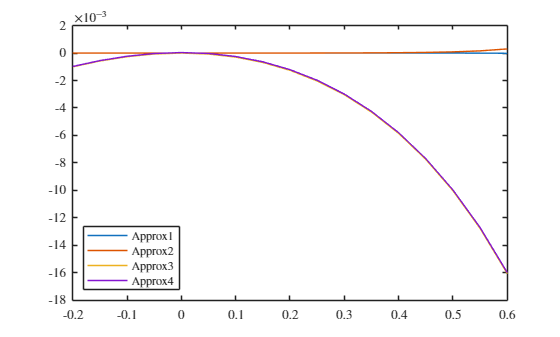




figure
plot(Pess_vec,Pe_exact - Pe_approx1,Pess_vec,Pe_exact - Pe_approx2,Pess_vec,Pe_exact - Pe_approx3, Pess_vec,Pe_exact-Pe_approx5)%,Pess_vec,Pe_exact - Pe_approx4)
legend("Approx1","Approx2","Approx3","Approx4",'location','sw')


return

## Extra Derivations


term(Pe,Pess) = sqrt(4*C1*H*wlim+2*C1*C3 + 2*C1*tau*Pess*(exp(-C1/tau*(Pe+C2-Pess))-1))
diffterm(Pe,Pess) = diff(term,Pess)
double(diffterm(Pe_base,0))
x = 0.01:0.01:0.5;
y = Pe_base + x .*(1+double(diffterm(Pe_base,0)))
plot(Pess_vec, Pe_exact, Pess_vec,Pe_approx3)

% I think approx3 is best for our application!


## More derivations

syms wlim H D C1 C2 C3 Pe Pess t s tau A B E F wlim
% B = C3*D^2 + 4*C1*H^2 + 2*C2*D*H + 2*D*H*Pe;
oldterm = C1/(D*s^2) + (B)/(D^2*(D + 2*H*s)) - (C2*D + 2*C1*H + D*Pe)/(D^2*s)
newterm = Pess/(D*s) - (4*H^2*Pess)/(D*(2*H - D*tau)*(D + 2*H*s)) %removed the tau*s+1 term
omega = oldterm + newterm
omegat = ilaplace(omega,t);
% with E = Pess/(2*H-D*tau)
omegat = (C1*t)/D - (C2*D + 2*C1*H + D*Pe - D*Pess)/D^sym(2) + (exp((-(D*t)/(2*H)))*(B - 4*H^2*D*E))/(2*D^2*H)
tnadir = solve(diff(omegat)==0, t)

omegatn = subs(omegat, t, tnadir)
omegatn = expand(omegatn)
% omegatneq = subs(omegatn, B, C3*D^2 + 4*C1*H^2 + 2*C2*D*H + 2*D*H*Pe)
eq0 = C3*D^2 + 4*C1*H^2 + 2*C2*D*H + 2*D*H*Pe - 4*D*H^2*E - 4*H^2*C1*exp(D/(2*H*C1)*(Pe+C2-Pess-D*wlim))
eq0 = subs(eq0, E, 0)
eq0 = subs(eq0, Pess, 0)
solve(Pe - exp(((C2 - Pe)))==0, Pe)

